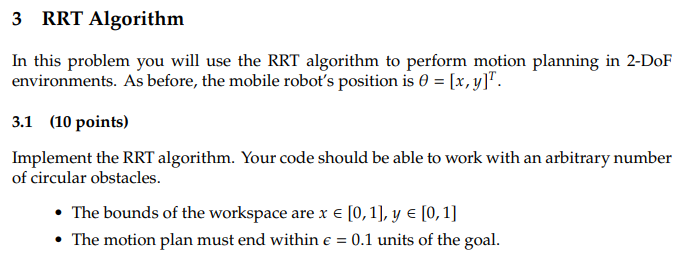

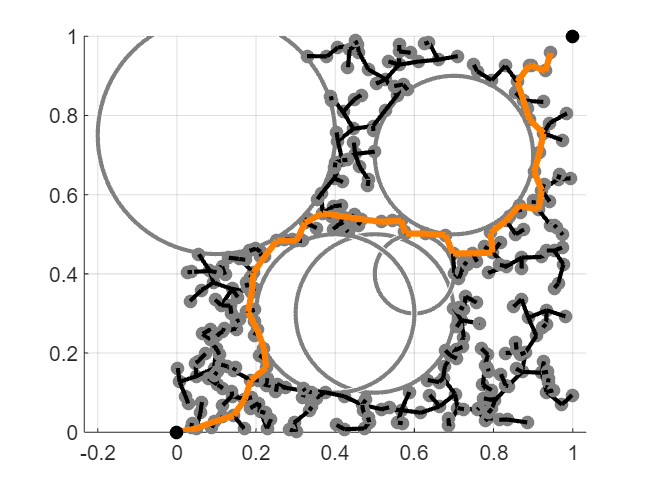

clear
close all

% Define start and goal positions
theta_start.coord = [0; 0];
theta_goal = [1; 1];

% Workspace bounds
x_bounds = [0, 1];
y_bounds = [0, 1];

% Define obstacles
% Each row is an obstacle with format: [center_x, center_y, radius]
obstacles = [
    0.5, 0.3, 0.2;
    0.7, 0.7, 0.2;
    0.6, 0.4, 0.1;
    0.4, 0.3, 0.2;
    0.1, 0.75, 0.3;
    % Add as many obstacles required, satisfying the condition of arbitrary
    % number of obstacles' inclusion
];

% RRT parameters
epsilon = 0.1; % Goal threshold
delta = 0.05;  % Step size
N = 1000;      % Number of iterations

% Visualize environment
figure
hold on
grid on
axis([x_bounds, y_bounds])
axis equal

% Plot obstacles
for i = 1:size(obstacles, 1)
    viscircles(obstacles(i, 1:2), obstacles(i, 3), 'Color', [0.5, 0.5, 0.5]);
end

% Initialize tree
theta_start.parent = 0;
G(1) = theta_start;

% Main RRT loop
for idx = 1:N
    if norm(G(end).coord - theta_goal) < epsilon
        break
    end

    % Random sample
    theta_rand = rand(2,1);

    % Nearest node
    [min_dist, theta_near_index] = min(vecnorm([G.coord] - theta_rand));
    theta_near = G(theta_near_index);

    % Step towards random sample
    vec_to_rand = theta_rand - theta_near.coord;
    if norm(vec_to_rand) > delta
        vec_to_rand = delta * vec_to_rand / norm(vec_to_rand);
    end
    theta_new.coord = theta_near.coord + vec_to_rand;

    % Collision check with all obstacles
    if isCollision(theta_new.coord, obstacles)
        continue;
    end

    % Add new node to tree
    theta_new.parent = theta_near_index;
    G = [G, theta_new];

    % Plotting
    plot(theta_new.coord(1), theta_new.coord(2), 'o', 'Color', [0.5, 0.5, 0.5], ...
    'MarkerFaceColor', [0.5, 0.5, 0.5]);
    line([theta_near.coord(1), theta_new.coord(1)], [theta_near.coord(2), theta_new.coord(2)], 'Color', 'k', 'LineWidth', 2);
end

% Trace back path
child_theta = G(end);
while child_theta.parent ~= 0
    parent_theta = G(child_theta.parent);
    line([child_theta.coord(1), parent_theta.coord(1)], [child_theta.coord(2), parent_theta.coord(2)], 'Color', [1, 0.5, 0], 'LineWidth', 3);
    child_theta = parent_theta;
end

% Plot start and goal
plot(theta_start.coord(1), theta_start.coord(2), 'ko', 'MarkerFaceColor', 'k');
plot(theta_goal(1), theta_goal(2), 'ko', 'MarkerFaceColor', 'k');


% Collision checking function

function collision = isCollision(coord, obstacles)
    collision = any(arrayfun(@(idx) norm(coord - obstacles(idx, 1:2)') < obstacles(idx, 3), 1:size(obstacles, 1)));
end